# Q3(b)

s = tf('s');
a = ureal('a',1,'Percentage',20);
G = [1/(s+a), 2/(s+3);
     1/(s+a), 1/(s+a)];
Wa = 0.2*(s+100)/(10*(s+10))*eye(2);
Wu = (1/50)*eye(2);
Wp = eye(2)*makeweight(100,5,1/1.995)

Wp =
 
  A = 
             x1        x2
   x1  -0.04327         0
   x2         0  -0.04327
 
  B = 
       u1  u2
   x1   2   0
   x2   0   2
 
  C = 
          x1     x2
   y1  2.153      0
   y2      0  2.153
 
  D = 
           u1      u2
   y1  0.5013       0
   y2       0  0.5013
 
Continuous-time state-space model.



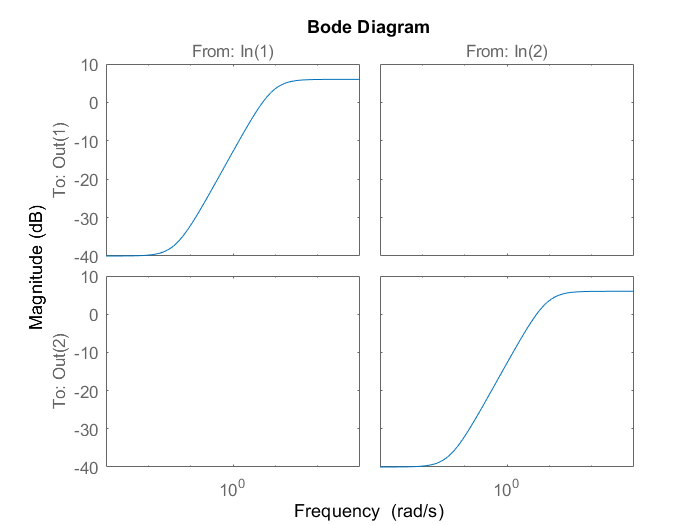

bodemag(1/Wp)

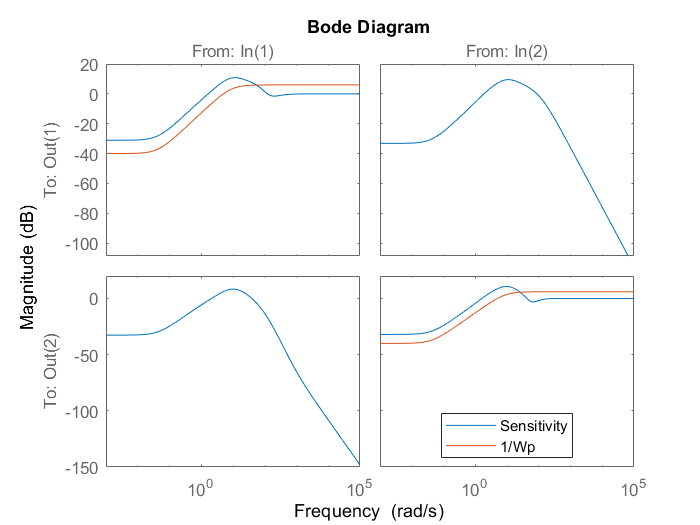

G_sample = usample(G,50);
%Fit uncertainity
[G_unc,info] = ucover(G_sample,G,4);
Wo = info.W1;

P = [zeros(2) Wo*G zeros(2) Wo*G;
     -Wa -Wa*G zeros(2) -Wa*G;
     zeros(2) zeros(2) zeros(2) Wu;
     Wp Wp*G Wp Wp*G;
     -eye(2) -G -eye(2) -G];

[K,CL,gamma] = hinfsyn(P,2,2);
S = eye(2) - feedback(G.NominalValue*K,eye(2));
bodemag(S,1/Wp)
legend("Sensitivity","1/Wp","Location","best")

# Q3(c)

%Taken from HW7 solutions
u1 = ultidyn('u1',[1 1]);
u2 = ultidyn('u2',[1 1]);
u = ultidyn('u',[2 2]);
G_diag = G*(eye(2)+[Wo*u1 0;0 Wo*u2]);
G_full = G*(eye(2)+Wo*u);
S_diag = eye(2)-feedback(G_diag*K,eye(2));
S_full = eye(2)-feedback(G_full*K,eye(2));

isstable(S_diag)

ans = logical
   1


[STABMARG,WCU] = robstab(S_diag);
mu_diag = 1/STABMARG.LowerBound

mu_diag = 0.8875

perf_diag = robustperf(Wp*S_diag);
mu_diag = 1/perf_diag.LowerBound

mu_diag = 6.2437


isstable(S_diag)

ans = logical
   1


[STABMARG,WCU] = robstab(S_full);
mu_full = 1/STABMARG.LowerBound

mu_full = 0.9178

perf_full = robustperf(Wp*S_full);
mu_full = 1/perf_full.LowerBound

mu_full = 6.2926

We can see that both of them have robust stability but not robust performance.